%raising a complex number to a power
z = sym(4 + 2*j) %declaring complex number

$$z = 4+2\,\mathrm{i}$$

v = z^5; %raising complex number to the desired power
%extracting polar coordinates
eval(angle(v)) 

ans = 2.3182

eval(abs(v))

ans = 1.7889e+03

clear all
%multiple roots
syms w %symbolic variables
z = sym(2+4*j); %declaring function


%calculating initial answer
%w = z^(1/3)
%eval(abs(w))
%eval(angle(w))

%calculating all solutions
sol = eval(solve(w^3 == z, w))

sol =    1.5366 + 0.5943i
  -0.2536 - 1.6279i
  -1.2830 + 1.0336i



%printing angles and moduli to see if they match my pen and paper
%calculations
abs(sol(1))

ans = 1.6475

angle(sol(1))

ans = 0.3690


abs(sol(2))

ans = 1.6475

angle(sol(2))

ans = -1.7253


abs(sol(3))

ans = 1.6475

angle(sol(3))

ans = 2.4634

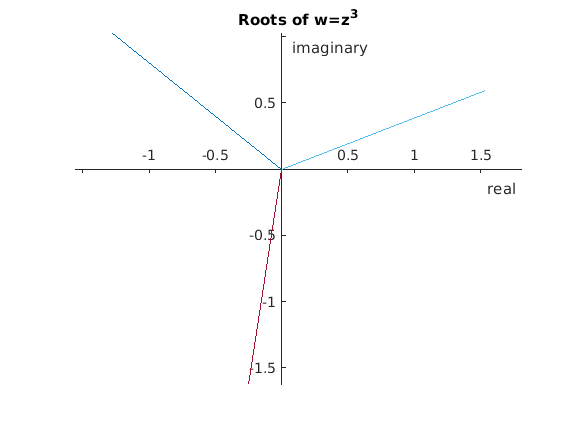


%plotting argand diagram
plot([0 real(sol(1))],[0 imag(sol(1))]) %to create a line from the origin we need the origin 0,0
hold on
plot([0 real(sol(2))],[0 imag(sol(2))])
plot([0 real(sol(3))],[0 imag(sol(3))])
hold off

xlabel("real")
ylabel("imaginary")
title("Roots of w=z^3")

%beautifying graph
ax=gca;
ax.YAxisLocation="origin";
ax.XAxisLocation="origin";
axis equal
box off